# Plotting the error surface

clear all;
close all;
clc;

load loc_20MU_grid_orthogonal.mat



#### Fontsize

fontsize=15;

Pt_dBm=30;%transmitt power in dBm

figure;
u=1;

x=linspace(x_min,x_max,ceil((x_max-x_min)/grid_size));
y=linspace(y_min,y_max,ceil((y_max-y_min)/grid_size));



pos_target(u,:)

ans =     3.1384    0.1060         0


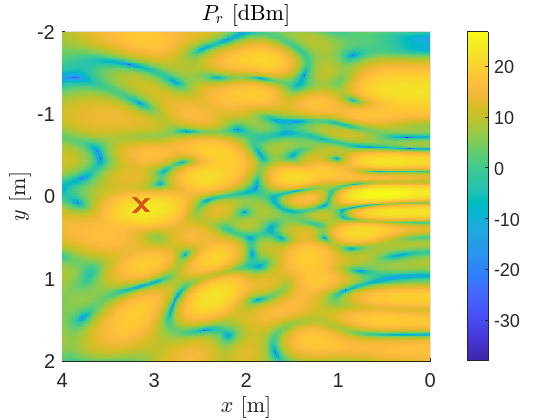


[X,Y] = meshgrid(x,y);
s=surf(X',Y',20*log10(abs(w_xy(:,:,u))) + 30+Pt_dBm); hold on;
s.EdgeColor = 'none';
colorbar
xlabel('$x$ [m]','Interpreter','latex');
ylabel('$y$ [m]','Interpreter','latex');
zlabel('Error [m]','Interpreter','latex');
set(gca,'FontSize',fontsize);

plot3(pos_target(u,1),pos_target(u,2),max(20*log10(abs(w_xy(:,:,2))))+ 30+Pt_dBm,'x','Color',"#D95319",'LineWidth',4,'MarkerSize',15);

axis([x_min ...
      x_max...
      y_min ...
      y_max...
      min(min(20*log10(abs(w_xy(:,:,u))) + 30+Pt_dBm)) ...
      max(max(20*log10(abs(w_xy(:,:,u))) + 30+Pt_dBm))]);

view([-180 90]);
title({'$P_r$ [dBm]'},'Interpreter','latex')

% view([-200 50])

#### Calculating the error


x=linspace(x_min,x_max,ceil((x_max-x_min)/grid_size));
y=linspace(y_min,y_max,ceil((y_max-y_min)/grid_size));
error_loc=zeros(1,MU_total);
for u=1:MU_total
    [MU_loc,I]=max(abs(w_xy(:,:,u)),[],'all','linear');
    [rows,~]=size(w_xy);
    col_max=floor(I/rows);
    row_max=I-col_max*rows;
    if col_max==0
        col_max=1;
    end
    if row_max==0
        row_max=1;
    end

    %abs(w_xy(row_max,col_max+1,MU_x,MU_y));
    %measuring the error
    error_loc(u)=norm(pos_target(u,:)-[x(row_max) y(col_max) 0]);
end

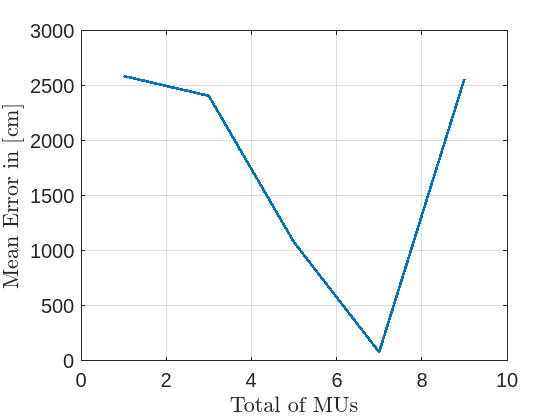



figure;
plot(1:2:MU_total-1,error_loc(1:2:end-1)*10^3,'LineWidth',2); grid on;
xlabel('Total of MUs','Interpreter','latex');
ylabel('Mean Error in [cm]','Interpreter','latex');
set(gca,'FontSize',fontsize);